clear all;clc;

## Load or specify category labels

addpath(genpath('../helperFunctions/'))
allTasks = {'Camel_v2_test_nn','Camel_novel_v2_test_nn','Camel_Rhino_test_nn','Camel_background_matrix'};

d = natsortfiles(dir('./behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

exp_colors = flipud([179,128,206;...
    211,107,172;...
    254,153,132;...
    248,214,86]/256);

allData.Camel_v2_test_nn.TestTarg(allData.Camel_v2_test_nn.TestTarg==398) = 198;

% Determine which shrews to use
shrewname={'Seymour','Dominic','Ryker'};
shrewID = 1:3;
nIt = 1000;

targdistPerf = cell(length(allTasks),length(shrewname));
targdistPerf_split1 = cell(length(allTasks),length(shrewname));
targdistPerf_split2 = cell(length(allTasks),length(shrewname));

for task = 1:length(allTasks)
    nTarg = length(unique(allData.(allTasks{task}).T_Expt_ID));
    nDist = length(unique(allData.(allTasks{task}).D_Expt_ID));

    targID = unique(allData.(allTasks{task}).T_Expt_ID);
    distID = unique(allData.(allTasks{task}).D_Expt_ID);
    for ts = 1:length(shrewname)
        for tt = 1:nTarg
            targdistPerf{task,ts}(tt,:) = nan(1,nDist);
            targdistPerf_split1{task,ts}(tt,:,:) = nan(nDist,nIt);
            targdistPerf_split2{task,ts}(tt,:,:) = nan(nDist,nIt);

            for dd = 1:nDist
                ntrials = sum(allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).D_Expt_ID==distID(dd));
                if ntrials >= 10
                    inclusion = allData.(allTasks{task}).ShrewID==shrewID(ts) & allData.(allTasks{task}).T_Expt_ID==targID(tt) & allData.(allTasks{task}).D_Expt_ID==distID(dd);
                    targdistPerf{task,ts}(tt,dd) = mean(allData.(allTasks{task}).correct(inclusion),'omitnan');

                    for samp = 1:nIt
                        idx = find(inclusion);
                        nidx_split = round(length(idx)/2);
                        rp = randperm(length(idx));
                        split1 = idx(rp(1:nidx_split));
                        split2 = idx(rp(nidx_split+1:end));
                        targdistPerf_split1{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split1),'omitnan');
                        targdistPerf_split2{task,ts}(tt,dd,samp) = mean(allData.(allTasks{task}).correct(split2),'omitnan');
                    end
                end
            end
        end
    end
end


## Plot between-shrew correlations of target/distractor performance

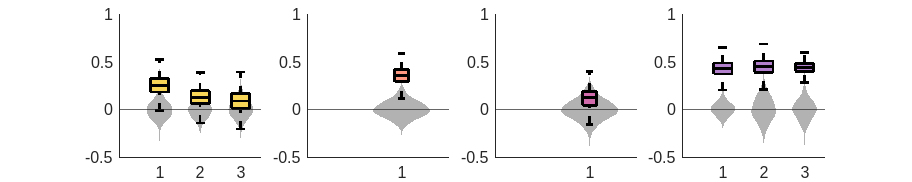

Se vs Do, r = 0.24707, p = 1
Se vs Ry, r = 0.12718, p = 0
Do vs Ry, r = 0.092139, p = 0
Se vs Do, r = 0.35374, p = 1
Do vs Ry, r = 0.12165, p = 0
Se vs Do, r = 0.43337, p = 1
Se vs Ry, r = 0.4551, p = 1
Do vs Ry, r = 0.44305, p = 1


figure('Renderer', 'painters', 'Position', [10 10 1500 300]);hold on;
perf_r = {};
perf_r_boot = {};
r_perm = {};
p_human975 = {};
for task = 1:length(allTasks)
    subplot(1,length(allTasks),task);hold on;
    nShrews = length(unique(allData.(allTasks{task}).ShrewID));
    uniqueShrew = unique(allData.(allTasks{task}).ShrewID);
    idx_comb = [1,2;1,3;2,3];
    if nShrews < 3
        idx_comb = uniqueShrew';
        nShrews = 1;
    end
    for i = 1:nShrews
        y1 = targdistPerf{task,idx_comb(i,1)};
        y2 = targdistPerf{task,idx_comb(i,2)};
        [perf1,perf2] = corr_fun(y1(:),y2(:));
        
        perf_r{task}(i) = corr(perf1,perf2,'rows','complete','Type','Spearman');
        perf_r_boot{task}(i,:) = bootstrp(1000,@(x,y) corr(x,y,'rows','complete','Type','Spearman'),perf1,perf2);

        for j = 1:nIt
            numtarg = length(perf1);
            idx1 = randperm(numtarg);
            idx2 = randperm(numtarg);
            r_perm{task}(i,j) = corr(perf1(idx1),perf2(idx2),'Rows','complete');
        end

        CI975_human = mean(r_perm{task}(i,:)) + 1.96*(std(r_perm{task}(i,:)));
        p_human975{task}(i) = mean(perf_r{task}(i))>CI975_human;

        disp([shrewname{shrewID(idx_comb(i,1))}(1:2),' vs ',shrewname{shrewID(idx_comb(i,2))}(1:2),', r = ',num2str(mean(perf_r{task}(i))),', p = ',num2str(p_human975{task}(i))])
    end

    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       temp = get(h1(j),'XData');
       violin(r_perm{task}(j,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
    end

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       patch(get(h1(j),'XData'),get(h1(j),'YData'),exp_colors(task,:),'FaceAlpha',1);
    end
    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    box off
    
    ylim([-0.5 1])
    yline(0)
end

## Within-shrew target/distractor correlations w null comparisons

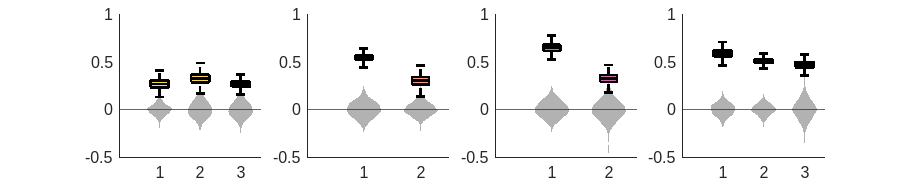

figure('Renderer', 'painters', 'Position', [10 10 1500 300]);hold on;
for task = 1:length(allTasks)
    subplot(1,length(allTasks),task);hold on;
    nShrews = length(unique(allData.(allTasks{task}).ShrewID));
    uniqueShrew = unique(allData.(allTasks{task}).ShrewID);
    r_perm{task} = nan(length(uniqueShrew),nIt);
    perf_r_boot{task} = nan(length(uniqueShrew),nIt);
    if nShrews < 3
        idx_comb = uniqueShrew';
        nShrews = 1;
    end
    if task ==3
        uniqueShrew = [1,2]';
    end
    for i = uniqueShrew'
        if task==3
            y1 = targdistPerf_split1{task,i+1};
            y2 = targdistPerf_split2{task,i+1};
        else
            y1 = targdistPerf_split1{task,i};
            y2 = targdistPerf_split2{task,i};
        end

        for j = 1:nIt
            [perf1,perf2] = corr_fun(y1(:,:,j),y2(:,:,j));

            numtarg = length(perf1);
            idx1 = randperm(numtarg);
            idx2 = randperm(numtarg);
            
            perf_r_boot{task}(i,j) = corr(perf1,perf2,'rows','complete','Type','Spearman');
            r_perm{task}(i,j) = corr(perf1(idx1),perf2(idx2),'Rows','complete');

        end
        
        perf_r{task}(i) = mean(perf_r_boot{task}(i,:));

        CI975_human = mean(r_perm{task}(i,:)) + 1.96*(std(r_perm{task}(i,:)));
        p_human975{task}(i) = mean(perf_r{task}(i))>CI975_human;
    end

    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       temp = get(h1(j),'XData');
       violin(r_perm{task}(j,:)','x',(temp(1)+temp(3))/2,'edgecolor','none','facecolor',[0.4 0.4 0.4],'mc',[],'medc',[]);
    end

    h1 = findobj(gca,'Tag','Box');
    for j=1:size(perf_r_boot{task},1)
       patch(get(h1(j),'XData'),get(h1(j),'YData'),exp_colors(task,:),'FaceAlpha',1);
    end
    h1 = boxplot(perf_r_boot{task}','colors',[0 0 0],'symbol','');
    set(h1,{'linew'},{2})

    box off
    ylim([-0.5 1])
    yline(0)
end